cd 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;addpath('Functions');startup;yalmip('clear')

Toolbox "yalmip:R20230609:all" added to the Matlab path.

The MATLAB interface for Gurobi 10.0.3 has been installed.

The directory
    C:\Program Files\MATLAB\Gurobi\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.



crossSectionsSet = [0.01;0.02;0.03];
ncross = numel(crossSectionsSet);
na = ncross;

## Ground structure

### Nodes

nodes.x = [0; 10; 0];                       % x coordinates of nodes
nodes.y = [0; 0; 10];                       % y coordinates of nodes
nodes.z = [0; 0; 0];                       % z coordinates of nodes
nnodes  = numel(nodes.x);                           % number of nodes

### Elements

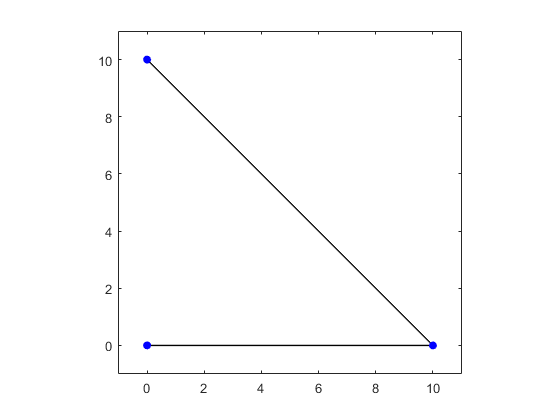

elements.nodes1 = [1; 3];   % elements starting nodes
elements.nodes2 = [2; 2];   % elements ending nodes
nelem = numel(elements.nodes1);  % number of elements  
nr = nelem;

plot([nodes.x(elements.nodes1) nodes.x(elements.nodes2)]', ...
     [nodes.y(elements.nodes1) nodes.y(elements.nodes2)]', ...
     'k','LineWidth',1);
hold on;
scatter(nodes.x, nodes.y, 'blue', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
hold off;

### Material and cross-section

elements.E = 10^4 ;    % Young moduli of individual elements
elements.Rho = 0.1 ;    

## Boundary conditions

### Restricted displacements

kinematic.x.nodes = [1; 3];             % node indices with restricted x-direction displacements
kinematic.y.nodes = [1; 3];             % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3];      % node indices with restricted z-direction displacements

### Load

loads.x.nodes = [2];             % node indices with x-direction forces
loads.x.value = [1];             % magnitude of the x-direction forces
loads.y.nodes = [2];          % node indices with y-direction forces
loads.y.value = [-3];          % magnitude of the y-direction forces 
loads.z.nodes = [];             % node indices with z-direction forces
loads.z.value = [];             % magnitude of the z-direction forces 

### Boundary conditions

dofs = true(nnodes,3);                % no kinematic boundary conditions
dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
dofs = reshape(dofs.',[],1);
nd = sum(dofs,"all");

## Optimization parameters

maximumStress = 60;
minimumStress = -60;
maximumDisplacement = 0.06;
minimumDisplacement = -0.06;

### Design variables

x = sdpvar(nelem * ncross,1);
s = sdpvar (nelem*ncross,1);
u = sdpvar(nnz(dofs),1);  

## FEM

deltaX = nodes.x(elements.nodes2) - nodes.x(elements.nodes1);
deltaY = nodes.y(elements.nodes2) - nodes.y(elements.nodes1);
deltaZ = nodes.z(elements.nodes2) - nodes.z(elements.nodes1);
lengths = sqrt(deltaX.^2 + deltaY.^2 + deltaZ.^2);
cosinus = [deltaX./lengths deltaY./lengths deltaZ./lengths];
codeNumbers = [repmat(elements.nodes1,1,3) repmat(elements.nodes2,1,3)]*3-2 + repmat([0 1 2 0 1 2], nelem, 1);
staticMatrix = sparse(codeNumbers(:), ...
                      repmat(1:nelem,1,6), ...
                      [-cosinus(:,1); -cosinus(:,2); -cosinus(:,3); cosinus(:,1); cosinus(:,2); cosinus(:,3);], ...
                      nnodes*3, nelem);
matrixB = full (staticMatrix(dofs,:) );

## Optimization problem formulation and solution

Fmin =  diag(minimumStress * diag ( kron( ones(nr,1) , crossSectionsSet) ) * x);
Fmax =  diag(maximumStress * diag ( kron( ones( nr,1) , crossSectionsSet) ) * x);

cmin =  reshape((elements.E*crossSectionsSet' ./ lengths .* (sum( matrixB .* (matrixB > 0) .* minimumDisplacement) + sum( matrixB .* (matrixB < 0) .* maximumDisplacement))').', 1, []);

Cmin = diag(cmin);

cmax = reshape((elements.E*crossSectionsSet' ./ lengths .* (sum( matrixB .* (matrixB > 0) .* maximumDisplacement) + sum( matrixB .* (matrixB < 0) .* minimumDisplacement))').', 1, []);
Cmax = diag(cmax);
I = ones(nelem * ncross);
B = repmat(matrixB, 1, na);

K = kron ( kron ((elements.E./lengths), crossSectionsSet), ones(nd,1)') .* B';

forceVector = sparse([loads.x.nodes*3-2; loads.y.nodes*3-1; loads.z.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value ], ...
                     nnodes*3, 1);
endForces = forceVector(reshape(dofs.', 1, [])');

### Constraints

y = double2sdpvar(sparse(2*na*nr+ nd,1));
y(1:nr*na) = x;
y(1+nr*na:nr*na+nd) = u;
y(1+nr*na+nd:2*nr*na+nd) = s;

#### Constraint 1: Inequality


$$A_{ineq} y \leq b
$$


**Matrix **$A_{ineq}
$

Aineq = double2sdpvar(sparse(4*na*nr,2*nr*na+nd));

*First collumn*

Aineq(1:nr*na,1:nr*na)              =  Fmin;
Aineq(1+nr*na:2*nr*na,1:nr*na)      = -Fmax;
Aineq(1+2*nr*na:3*nr*na,1:nr*na)    = -Cmin;
Aineq(1+3*nr*na:4*nr*na,1:nr*na)    =  Cmax;

*Second collumn*

Aineq(1+2*nr*na:3*nr*na,1+nr*na:nr*na+nd)    =  K;
Aineq(1+3*nr*na:4*nr*na,1+nr*na:nr*na+nd)    = -K;

*Third collumn*

Aineq(1:nr*na,1+nr*na+nd:2*nr*na+nd)              = -I;
Aineq(1+nr*na:2*nr*na,1+nr*na+nd:2*nr*na+nd)      =  I;
Aineq(1+2*nr*na:3*nr*na,1+nr*na+nd:2*nr*na+nd)    =  I;
Aineq(1+3*nr*na:4*nr*na,1+nr*na+nd:2*nr*na+nd)    = -I;

**Vector **$b
$

b = sparse(4*na*nr,1);
b(1+2*nr*na:3*nr*na,1) = -diag(Cmin);
b(1+3*nr*na:4*nr*na,1) =  diag(Cmax);

**Inequation**

constIneq = Aineq * y <= b;

#### Constraint 2: Equality


$$A_{eq} y = b_{eq}
$$


**Matrix **$A_{eq}
$

Aeq = sparse(nd + nr,2*nr*na+nd);
Aeq(nd+1:nd+nr,1:nr*na) = ones(nr,nr*na);
Aeq(1:nd,nr*na+nd+1:nr*na+nd+nr*na) = B;

**Vector **$b_{eq}$

beq = sparse(nd + nr,1);
beq(1:nd,1) = endForces;
beq(nd+1:nd+nr,1) = ones(nr,1);
constEq = Aeq * y >= beq;

#### Constraint 3: Box constraints

***Lower bound***

lb = sparse(nr*na*2+nd,1);
lb(1:nr*na) = 0;
lb(nr*na+1:nr*na + nd) = minimumDisplacement;
lb(nr*na+nd+1:nr*na*2+nd) = kron(minimumStress*ones(nr,1),crossSectionsSet);

**Upper bound**

ub = sparse(nr*na*2+nd,1);
ub(1:nr*na) = 1;
ub(nr*na+1:nr*na + nd) = maximumDisplacement;
ub(nr*na+nd+1:nr*na*2+nd) = kron(maximumStress*ones(nr,1),crossSectionsSet);

***Box constraint***

constBox = (lb <= y) & (y <= ub);

### Objective function

m = elements.Rho * kron(lengths,ones(na,1))' .* kron(ones(nr,1),crossSectionsSet)';
M = sparse(1,nr*na*2 + nd);
M(1:nr*na) = m;
objective = M * y

Linear scalar (real, 6 variables)
Coefficients range: 0.01 to 0.042426


### Solution

ops = sdpsettings('solver', 'quadprog');  % Nastavení Gurobi solveru s metodou BnB
ops = sdpsettings(ops, 'verbose', 2);
constraints = [ ...
                constIneq,...
                constEq,...
                constBox...
                ];  % Kombinace všech omezení
optimize(constraints, objective, ops);

## Post-procesing

### Write solution

fprintf('Optimized objective: %f\n', value(objective));

Optimized objective: NaN


value(x)

ans =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN


### Plotting

Plot the optimal design. Note that the dimensions are scaled.